addpath('\\badwwmi-k04-qtm\\Data_QTM\_data\run19\MeasurementProtocolHT')

## Templates

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, B mT)

% clear % plot raw transmission
% vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
% load('', vari{:})
% table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% % select power-range
% powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);
% 
% figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% 
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end
% 
% ylabel('|S_{21}| (dB)','FontSize',font_size)
% xlabel('Frequency (GHz)','FontSize',font_size)
% legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, B mT)

% clear % plot raw S21 and normalized S21, phase and delay
% vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
% load('', vari{:})
% table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% % select power-range
% powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);
% 
% % normalize to highest selected power
% zz_norm = zz(:,ind_low:ind_high) - zz(:,ind_high);
% zzph_norm = zzph(:,ind_low:ind_high) - zzph(:,ind_high);
% zzed_norm = zzed(:,ind_low:ind_high) - zzed(:,ind_high);
% 
% % subplot properties
% n_sub = 4; % number of subplots
% margin_l = 0.1; margin_r = 0.05; height_sub = 0.225; delta_sub = 0.01;
% font_size = 12;
% 
% figure
% for i = 1:n_sub
%     axes(i) = subplot('Position', [margin_l 1-i*height_sub-i*delta_sub 1-margin_l-margin_r height_sub]);
% end
% hold(axes, 'on')
% cc = turbo(length(powers));
% 
% for i = 1:length(powers)
%     plot(axes(1), yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
%     plot(axes(2), yy/1e9, zz_norm(:,i), 'Color', cc(i,:)) % normalized S21
%     plot(axes(3), yy/1e9, zzph_norm(:,i), 'Color', cc(i,:)) % normalized phase
%     plot(axes(4), yy/1e9, zzed_norm(:,i), 'Color', cc(i,:)) % normalized group delay
% end
% 
% ylabel(axes(1), '|S_{21}| (dB)','FontSize',font_size)
% ylabel(axes(2), 'Norm. |S_{21}| (dB)','FontSize',font_size)
% ylabel(axes(3), 'Norm. phase (deg)','FontSize',font_size)
% ylabel(axes(4), 'Norm. group delay','FontSize',font_size)
% xlabel(axes(4), 'Frequency (GHz)','FontSize',font_size)
% legend(axes(1), 'Location', 'northoutside', 'NumColumns', length(powers))
% set(axes(1:end-1), 'xTickLabel', '')
% linkaxes(axes, 'x');

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, B - B mT, pow dBm)

% clear % plot field sweep
% vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
% load('', vari{:})
% table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
%     {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
%     'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})
% [yy, B_field, zz, zzph, zzed] = crop_data( ...
%     yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

% zz_norm = normalize_freq_field_mean(zz);
% % zz_norm = normalize_zero_field(zz);
% figure; plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

% zzph_norm = normalize_freq_field_mean(zzph);
% figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
%         {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

% zzed_norm = normalize_freq_field_mean(zzed);
% figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
%         {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

#### **25-03-04 @ 09:29:21, 2.6GHz-HT (2.63-2.67 GHz, -1.0 - 5.0 mT, -42 dBm)**

clear % plot field sweep
vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\B_sweep_r19s1_2_nat_Er_CWO_2630_2670MHz_-1_5mT_7mK_2.6GHz_HT_03-Apr-2025_@_09-29-21\B_sweep_r19s1_2_nat_Er_CWO_2630_2670MHz_-1_5mT_7mK_2.6GHz_HT@_09-29-21.mat', vari{:})
table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
    {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
    'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})

ans = 1×5 table
       Power          Step        Points     Bandwidth     Averages
    ___________    __________    ________    __________    ________

    {'-42 dBm'}    {'0.1 mT'}    {'8001'}    {'200 Hz'}     {'1'}  


[yy, B_field, zz, zzph, zzed] = crop_data( ...
    yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

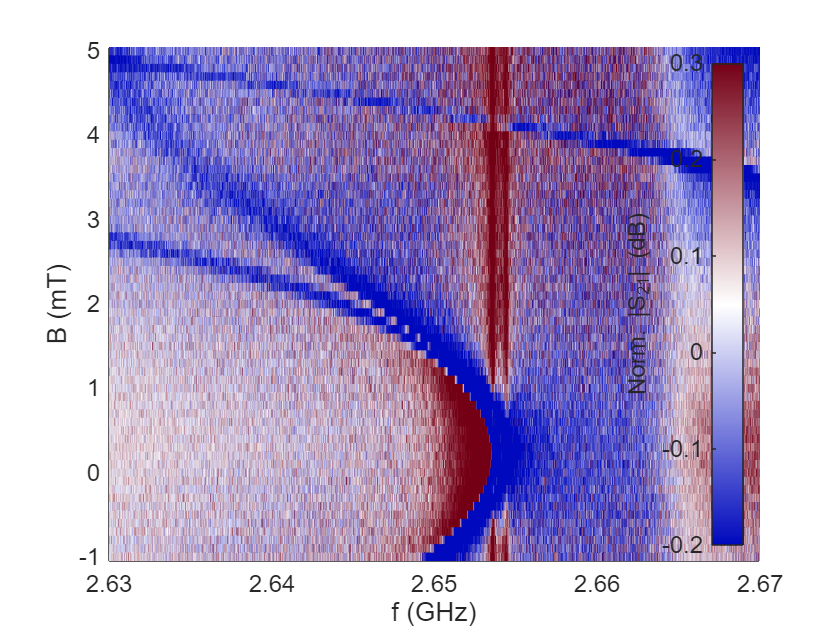

zz_norm = normalize_freq_field_mean(zz);
% zz_norm = normalize_zero_field(zz);
figure; plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
        {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

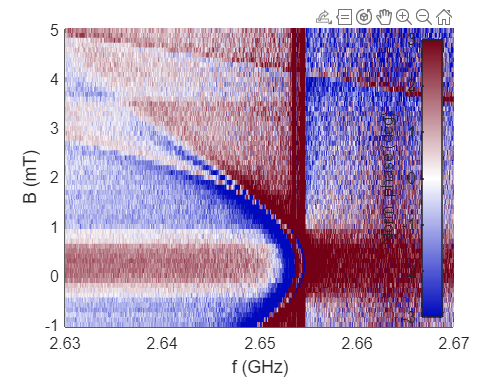

zzph_norm = normalize_freq_field_mean(zzph);
figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
        {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

zzed_norm = normalize_freq_field_mean(zzed);
figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
        {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

#### **25-03-04 @ 11:18:24, 2.6GHz-HT (2.68-2.72 GHz, -1.0 - 5.0 mT, -42 dBm)**

clear % plot field sweep
vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\B_sweep_r19s1_2_nat_Er_CWO_2680_2720MHz_-1_5mT_7mK_3.2GHz_HT_03-Apr-2025_@_11-18-34\B_sweep_r19s1_2_nat_Er_CWO_2680_2720MHz_-1_5mT_7mK_3.2GHz_HT@_11-18-34.mat', vari{:})
table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
    {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
    'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})

ans = 1×5 table
       Power          Step        Points     Bandwidth     Averages
    ___________    __________    ________    __________    ________

    {'-42 dBm'}    {'0.1 mT'}    {'8001'}    {'200 Hz'}     {'1'}  


[yy, B_field, zz, zzph, zzed] = crop_data( ...
    yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

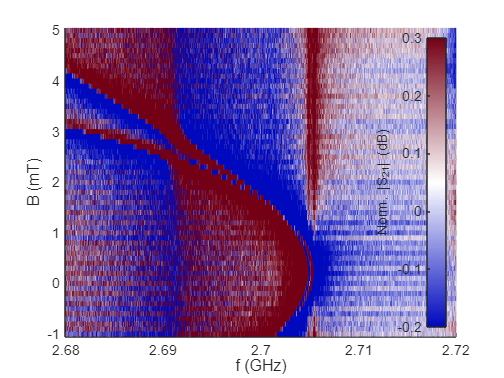

zz_norm = normalize_freq_field_mean(zz);
% zz_norm = normalize_zero_field(zz);
figure; plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
        {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

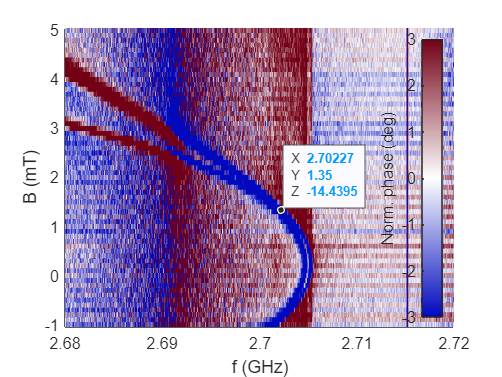

zzph_norm = normalize_freq_field_mean(zzph);
figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
        {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

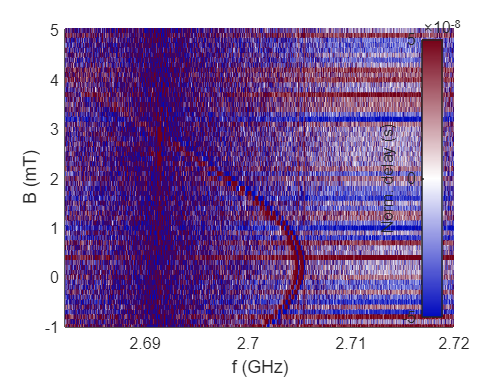

zzed_norm = normalize_freq_field_mean(zzed);
figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
        {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

#### **25-03-04 @ 09:58:48, 2.7GHz-HT (2.68-2.72 GHz, -1.0 - 5.0 mT, -42 dBm)**

clear % plot field sweep
vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\B_sweep_r19s1_2_nat_Er_CWO_2685_2725MHz_-2_2mT_7mK_Near-Zero-Field_2.7_05-Apr-2025_@_09-58-48\B_sweep_r19s1_2_nat_Er_CWO_2685_2725MHz_-2_2mT_7mK_Near-Zero-Field_2.7@_09-58-48.mat', vari{:})
table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
    {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
    'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})

ans = 1×5 table
       Power          Step         Points     Bandwidth     Averages
    ___________    ___________    ________    __________    ________

    {'-42 dBm'}    {'0.01 mT'}    {'8001'}    {'200 Hz'}     {'1'}  


[yy, B_field, zz, zzph, zzed] = crop_data( ...
    yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

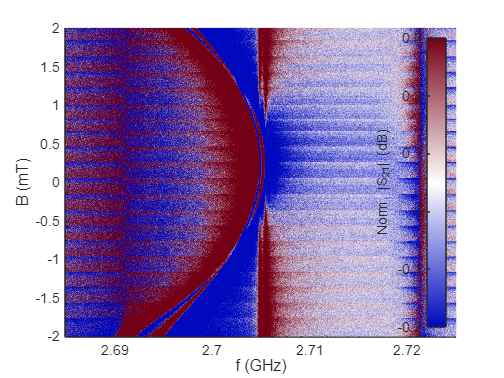

zz_norm = normalize_freq_field_mean(zz);
% zz_norm = normalize_zero_field(zz);
figure; plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
        {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

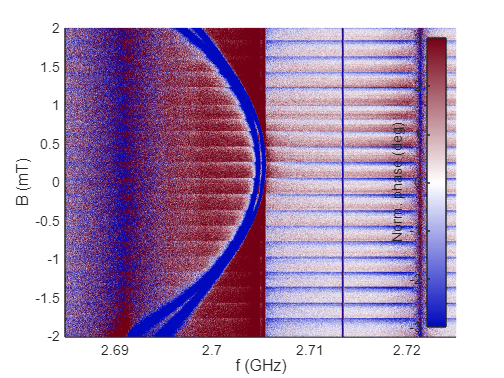

zzph_norm = normalize_freq_field_mean(zzph);
figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
        {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

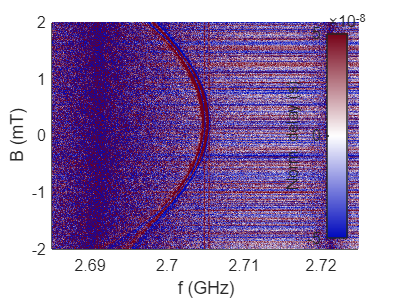

zzed_norm = normalize_freq_field_mean(zzed);
figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
        {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

#### **25-04-09 @ 16:20:21, 30mT Sweep HT (2.2-2.8 GHz, -2.0 - 30 mT, -42 dBm)**

clear % plot field sweep
vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\B_sweep_r19s1_2_nat_Er_CWO_2200_2800MHz_-2_30mT_7mK_-2-30mT_09-Apr-2025_@_16-20-01\B_sweep_r19s1_2_nat_Er_CWO_2200_2800MHz_-2_30mT_7mK_-2-30mT@_16-20-01.mat", vari{:})
table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
    {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
    'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})

ans = 1×5 table
       Power          Step        Points     Bandwidth     Averages
    ___________    __________    ________    __________    ________

    {'-42 dBm'}    {'0.2 mT'}    {'8001'}    {'200 Hz'}     {'1'}  


[yy, B_field, zz, zzph, zzed] = crop_data( ...
    yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

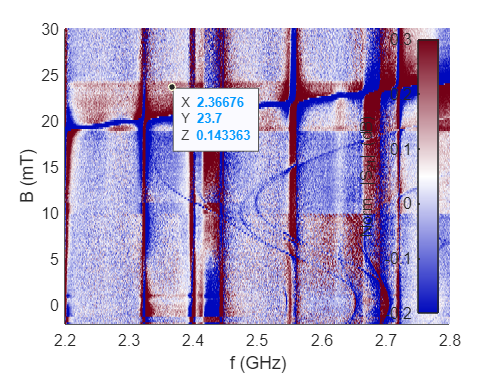

zz_norm = normalize_freq_field_mean(zz);
% zz_norm = normalize_zero_field(zz);

figure; 
plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
        {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

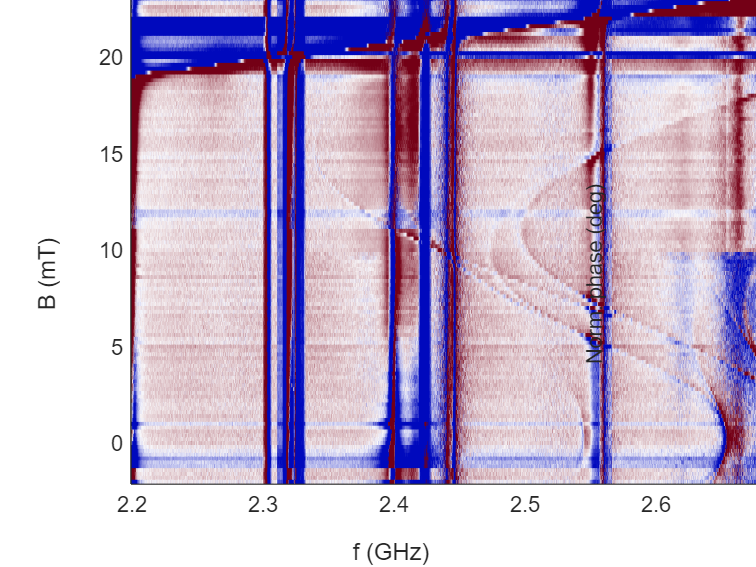

zzph_norm = normalize_freq_field_mean(zzph);
figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
        {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

zzed_norm = normalize_freq_field_mean(zzed);
figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
        {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

#### **25-04-30 @ 09:19:32, 5mT Sweep HT (2.48-2.58 GHz, 5.0 - 8.0 mT, -42 dBm)**

clear % plot field sweep
vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\B_sweep_r19s1_2_nat_Er_CWO_2480_2580MHz_4.8_8.2mT_7mK_-2-2mT_30-Apr-2025_@_09-42-12\B_sweep_r19s1_2_nat_Er_CWO_2480_2580MHz_4.8_8.2mT_7mK_-2-2mT@_09-42-12.mat', vari{:})
table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
    {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
    'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})

ans = 1×5 table
       Power          Step         Points     Bandwidth     Averages
    ___________    ___________    ________    __________    ________

    {'-42 dBm'}    {'0.05 mT'}    {'8001'}    {'200 Hz'}     {'1'}  


[yy, B_field, zz, zzph, zzed] = crop_data( ...
    yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

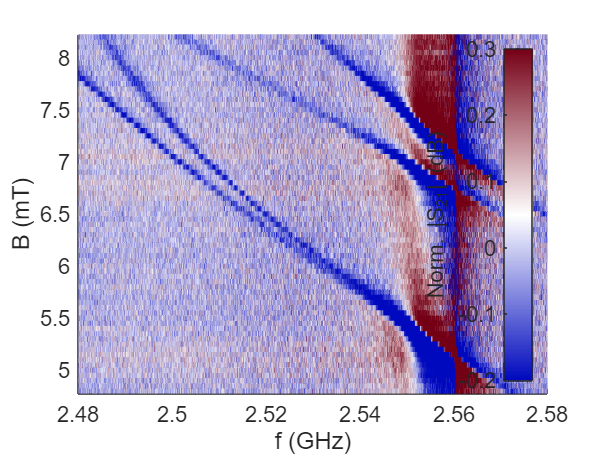

Unrecognized function or variable 'd'.

zz_norm = normalize_freq_field_mean(zz);
% zz_norm = normalize_zero_field(zz);

figure; 
plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
        {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

zzph_norm = normalize_freq_field_mean(zzph);
figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
        {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

zzed_norm = normalize_freq_field_mean(zzed);
figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
        {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});


#### **25-04-30 @ 11:16:52, 12-14mT Sweep HT (2.48-2.56 GHz, 5.0 - 8.0 mT, -42 dBm)**

clear % plot field sweep
vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\B_sweep_r19s1_2_nat_Er_CWO_2480_2560MHz_11.8_14.2mT_7mK_12-14mT_30-Apr-2025_@_11-16-52\B_sweep_r19s1_2_nat_Er_CWO_2480_2560MHz_11.8_14.2mT_7mK_12-14mT@_11-16-52.mat', vari{:})
table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
    {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
    'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})

ans = 1×5 table
       Power          Step         Points     Bandwidth     Averages
    ___________    ___________    ________    __________    ________

    {'-42 dBm'}    {'0.05 mT'}    {'8001'}    {'200 Hz'}     {'1'}  


[yy, B_field, zz, zzph, zzed] = crop_data( ...
    yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

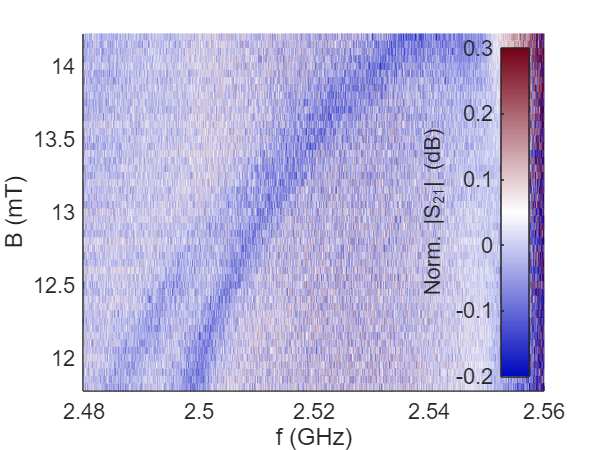

zz_norm = normalize_freq_field_mean(zz);
% zz_norm = normalize_zero_field(zz);

figure; 
plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
        {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

zzph_norm = normalize_freq_field_mean(zzph);
figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
        {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

zzed_norm = normalize_freq_field_mean(zzed);
figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
        {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

